clear variables; close all; clc;
data = readtable("/home/achadbo/Desktop/Autoland/7-3-2024_1000/states.csv");
x = data.x;
h = data.h - 376;
y = data.y;
data_len = length(x);

data2 = readtable("/home/achadbo/Desktop/Autoland/7-2-2024_1000/states.csv");
x2 = data2.x;
h2 = data2.h - 376;
y2 = data2.x

y2 =   998.9950
  990.7576
  982.9881
  975.7678
  968.4390
  960.5791
  953.3936
  946.2487
  938.6976
  931.2127


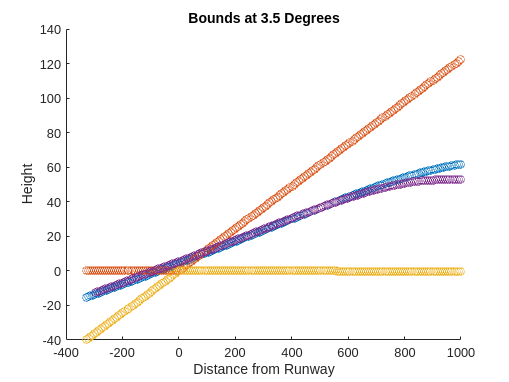



slope = tand(3.5);
slope_x = x.*slope;

r = tand(3.5) * sqrt(x.^2 + slope_x.^2);
u_bounds = slope_x + r;
l_bounds = slope_x - r;

in_bound_rows = find(h <= u_bounds & h >= l_bounds & y <= r & y >= -r);
in_bound_data = data(in_bound_rows, ["x", "y", "h"]);
x_in = in_bound_data.x;
y_in = in_bound_data.y;
h_in = in_bound_data.h - 376;

scatter(x, h);
hold on;
%scatter(x_in, h_in);
scatter(x, u_bounds);
scatter(x, l_bounds);
scatter(x2(1:data_len), h2(1:data_len));
xlabel("Distance from Runway");
ylabel("Height");
title("Bounds at 3.5 Degrees");
hold off;

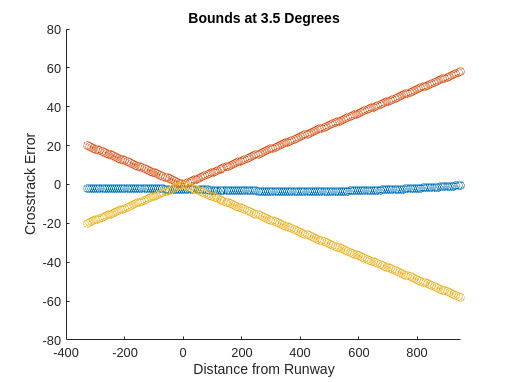


scatter(x, y);
hold on;
% scatter(x_in, y_in);
scatter(x, r);
scatter(x, -r);
xlabel("Distance from Runway");
ylabel("Crosstrack Error");
title("Bounds at 3.5 Degrees");
hold off;

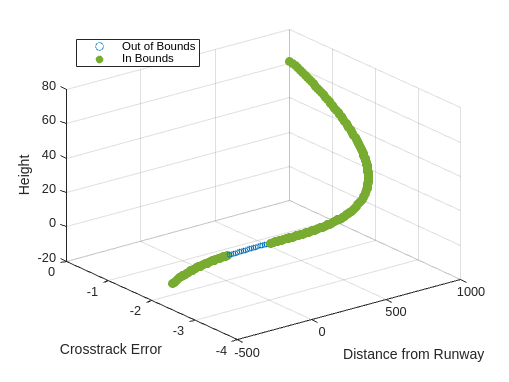


green = [0.4660 0.6740 0.1880];
blue = [0 0.4470 0.7410];
scatter3(x, y, h, 15, blue);
hold on;
% scatter3(x, y, u_bounds);
% scatter3(x, y, l_bounds);
% scatter3(x, r, h);
% scatter3(x, -r, h);
scatter3(x_in, y_in, h_in, 50, green, "filled");
xlabel("Distance from Runway");
ylabel("Crosstrack Error");
zlabel("Height");
legend({"Out of Bounds", "In Bounds"}, 'Location', 'northwest');
hold off;